# Finite-sample Bias and Standard Error Verification

## Notes

This solution relies heavily on the maximum likelihood solution, especially for the Probit standard error Monte Carlo.

This solution first shows a simple example, and then wraps it in a loop to perform the Monte Carlo.

## Setup

Clean up everything

clear all
close all
clc
% Reset rng to make runs the same
rng('default')

## Method of Moments Estimator

A useful technique when conducting a Monte Carlo is to start with a single iteration of the core code

% Simulate
x = chi2rnd(5,10,1);
% Estimate parameters
mu = mean(x);
sigma2 = mean((x-mu).^2);
% Construct Errors
errors = [x - mu (x-mu).^2-sigma2];
n = length(x);
% Estimate asymptotic covariance
asymp_cov = errors'*errors / n;

## Repeating using a loop

After the core code is correct, wrapping it in a loop to conduct the MC is usually easy

% Array to hold the 1000 asymptotic covariance estimators
asymp_cov = zeros(2,2,1000);
parameters = zeros(1000,2);
for i=1:1000
    % Simulate
    x = chi2rnd(5,10,1);
    % Estimate parameters
    mu = mean(x);
    sigma2 = mean((x-mu).^2);
    % Save parameters
    parameters(i,:) = [mu sigma2];
    % Estimate asymptotic covariance
    errors = [x - mu (x-mu).^2-sigma2];
    n = length(x);
    asymp_cov(:,:,i) = errors'*errors / n;
end
% Compare covariance
disp('From data')

From data


disp(cov(parameters))

    0.9159    3.1658
    3.1658   34.9983



disp('Avg Asymp. Covariance')

Avg Asymp. Covariance


disp(mean(asymp_cov,3)/n)

    0.8755    2.7738
    2.7738   27.0168



## Checking the Coverage

Check the 10%, 5% and 1% 2-sided coverage. Ideally this would be close to 10%, 5% and 1%

std_err = zeros(1000,2);
z = zeros(1000,2);
for i=1:1000
    std_err = sqrt(diag(asymp_cov(:,:,i)/n));
    z(i,:) = (parameters(i,:) - [5 10])./std_err';
end
% Coverage for 10%, 5% and 1%, all 2-sided
disp('10% CI coverage')

10% CI coverage


disp(mean(abs(z) > norminv(.95)))

    0.1700    0.4320



disp('5% CI coverage')

5% CI coverage


disp(mean(abs(z) > norminv(.975)))

    0.1070    0.3850



disp('1% CI coverage')

1% CI coverage


disp(mean(abs(z) > norminv(.995)))

    0.0590    0.3090



## Density plot against a Standard normal

pltdens can be used to produce density plots. The outputs are the estimated pdf value (f) and the location (y).

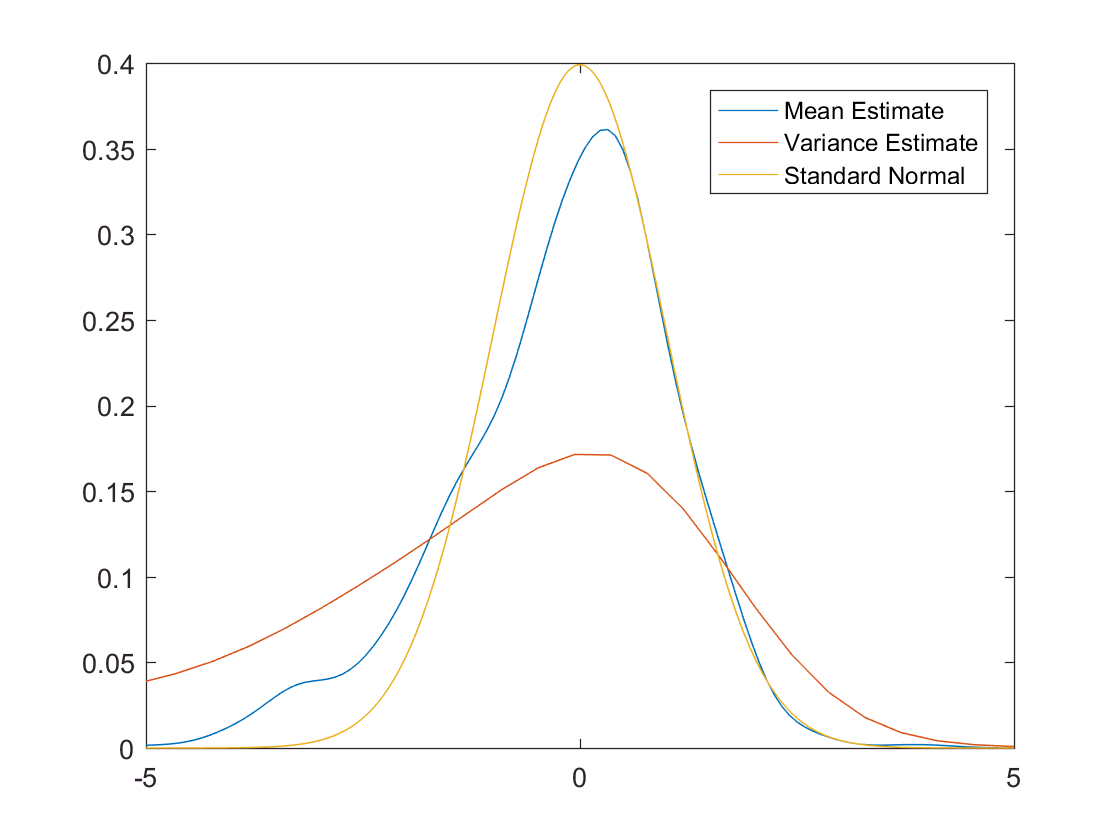

% Run pltdens to get f and y
[~,f1,y1]=pltdens(z(:,1));
[~,f2,y2]=pltdens(z(:,2));
% Compute the same for a std normal
y3 = -5:.01:5;
f3 = normpdf(y3,0,1);
% Plot
h = plot(y1,f1,y2,f2,y3,f3);
legend('Mean Estimate','Variance Estimate','Standard Normal')
ax = axis;
ax(1) = -5;
ax(2) = 5;
axis(ax)

## Repeating for different sample sizes

Once the core code has been written, another loop can be used to loop over sample sizes

Sample size


     5



Bias


   -0.0134   -2.1073



Covariance of estimates


    3.0822
   18.7692



Std Dev. from CLT


    2.8094
   13.4519



Ratio - Estimates divided by Asymp.


    1.0971
    1.3953



10% CI coverage


    0.2450    0.5510



5% CI coverage


    0.1730    0.5110



1% CI coverage


    0.1120    0.4510



Sample size


    10



Bias


   -0.0314   -1.1152



Covariance of estimates


    3.1649
   21.0863



Std Dev. from CLT


    2.9807
   17.5236



Ratio - Estimates divided by Asymp.


    1.0618
    1.2033



10% CI coverage


    0.1730    0.4170



5% CI coverage


    0.1290    0.3690



1% CI coverage


    0.0800    0.3060



Sample size


    50



Bias


    0.0237   -0.1553



Covariance of estimates


    3.2127
   19.6359



Std Dev. from CLT


    3.1376
   19.7744



Ratio - Estimates divided by Asymp.


    1.0239
    0.9930



10% CI coverage


    0.1210    0.1960



5% CI coverage


    0.0670    0.1620



1% CI coverage


    0.0220    0.1140



Sample size


   100



Bias


   -0.0052   -0.1937



Covariance of estimates


    3.1780
   20.2705



Std Dev. from CLT


    3.1315
   19.8542



Ratio - Estimates divided by Asymp.


    1.0149
    1.0210



10% CI coverage


    0.1120    0.1760



5% CI coverage


    0.0600    0.1320



1% CI coverage


    0.0210    0.0770



Sample size


   200



Bias


    0.0071   -0.0144



Covariance of estimates


    3.1782
   21.4475



Std Dev. from CLT


    3.1600
   20.9088



Ratio - Estimates divided by Asymp.


    1.0058
    1.0258



10% CI coverage


    0.1060    0.1450



5% CI coverage


    0.0610    0.1010



1% CI coverage


    0.0110    0.0420



Sample size


   500



Bias


    0.0044    0.0288



Covariance of estimates


    3.0554
   20.4207



Std Dev. from CLT


    3.1668
   20.8931



Ratio - Estimates divided by Asymp.


    0.9648
    0.9774



10% CI coverage


    0.0940    0.1110



5% CI coverage


    0.0420    0.0620



1% CI coverage


    0.0060    0.0230



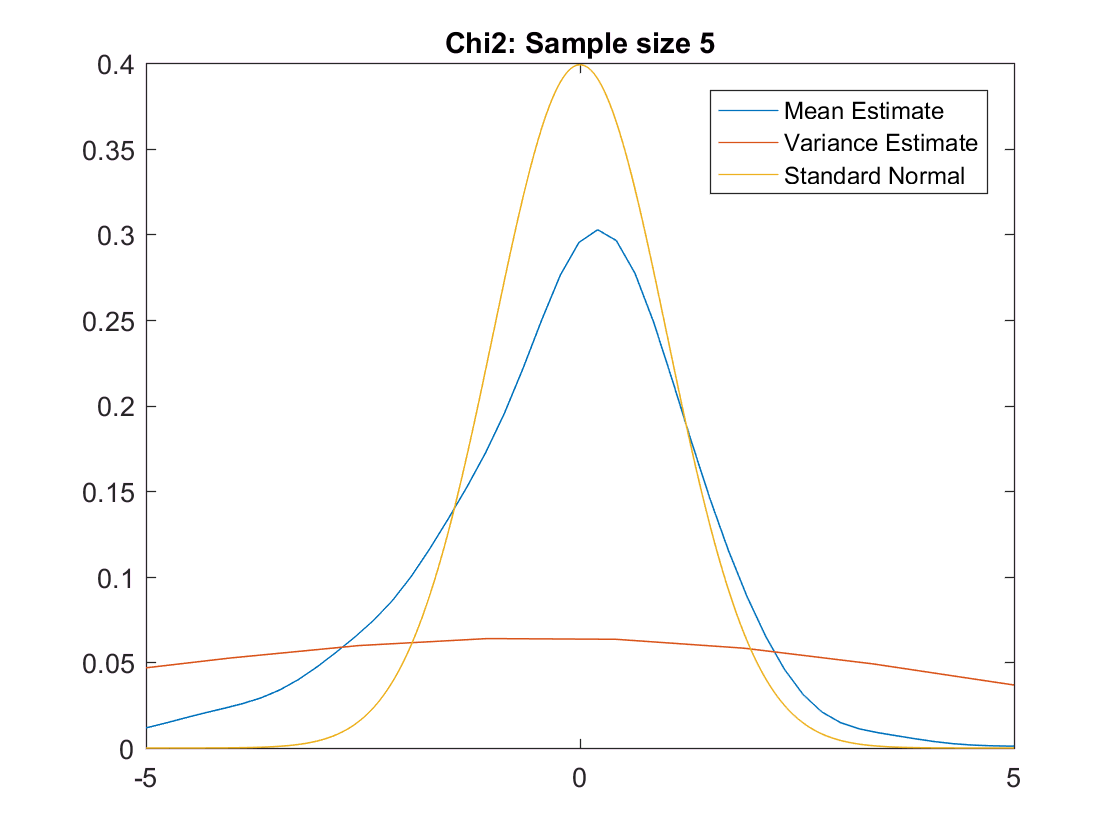

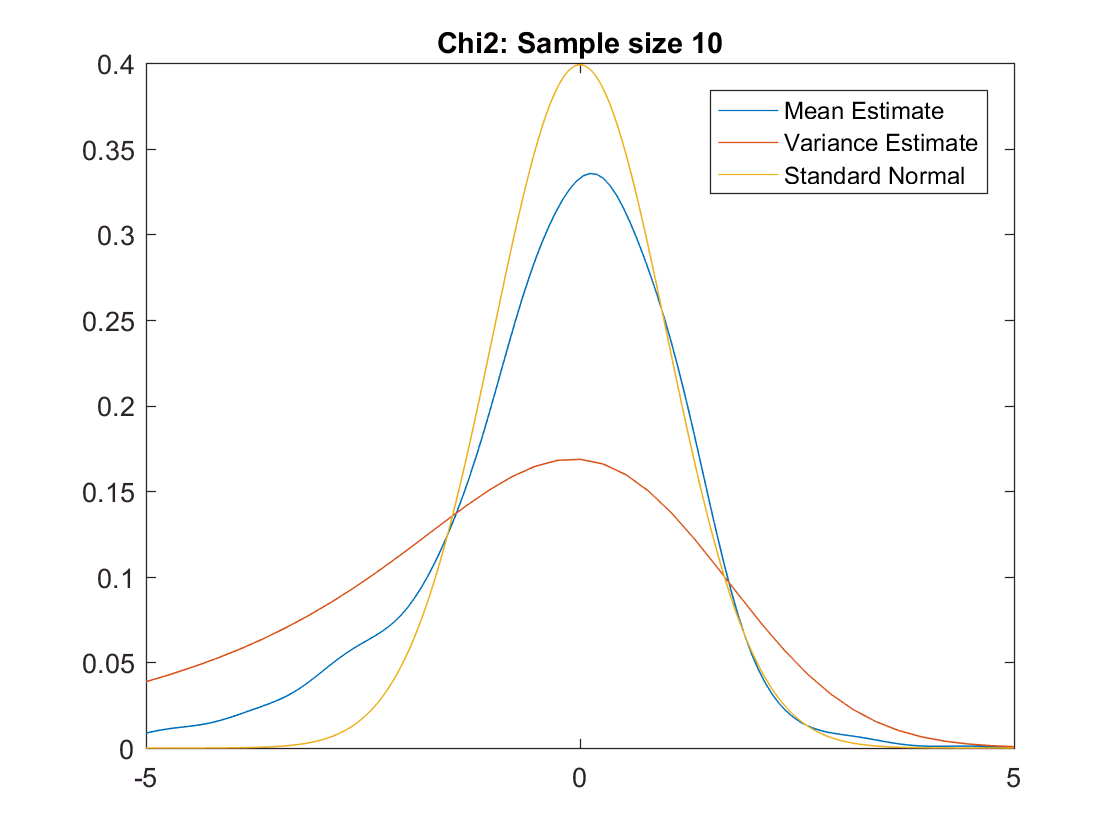

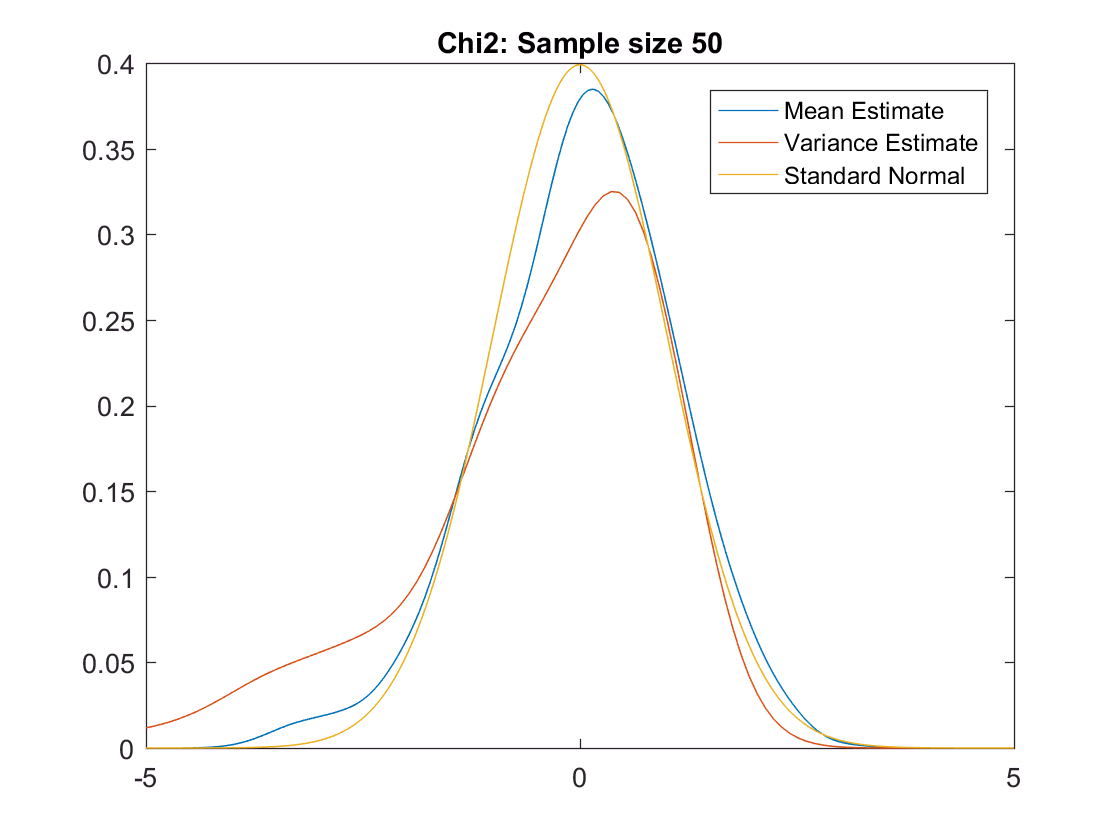

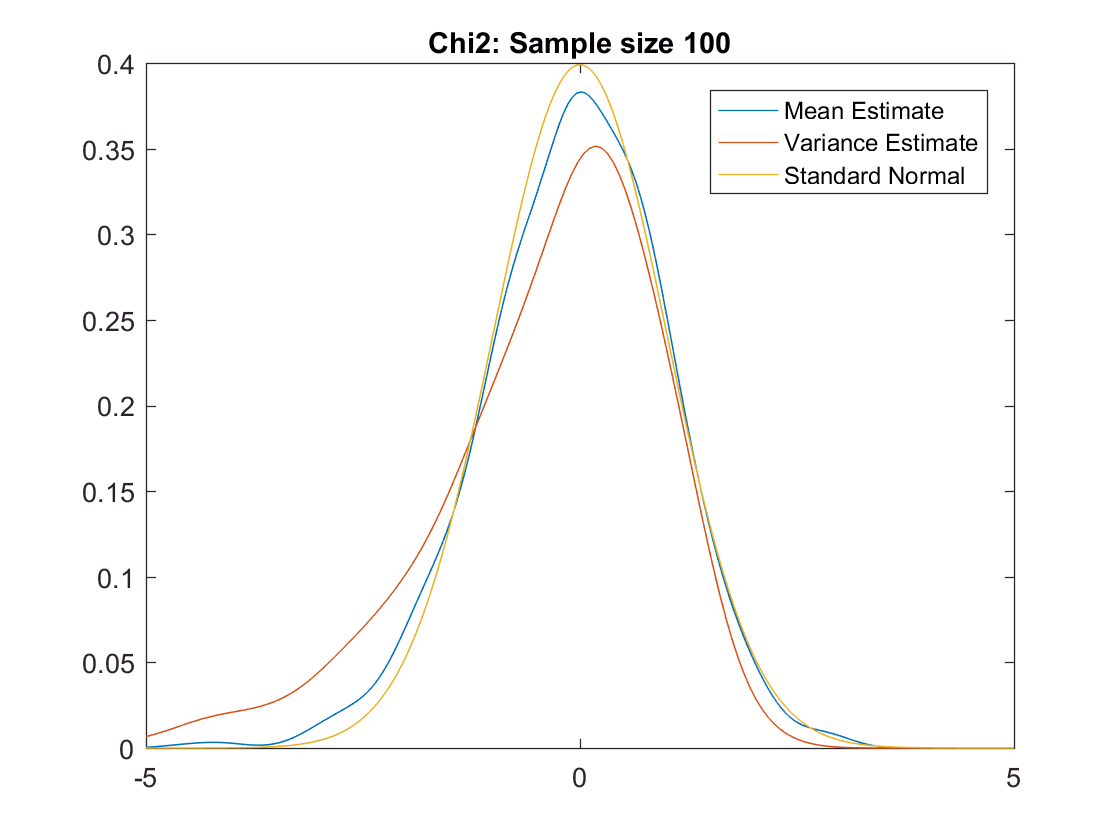

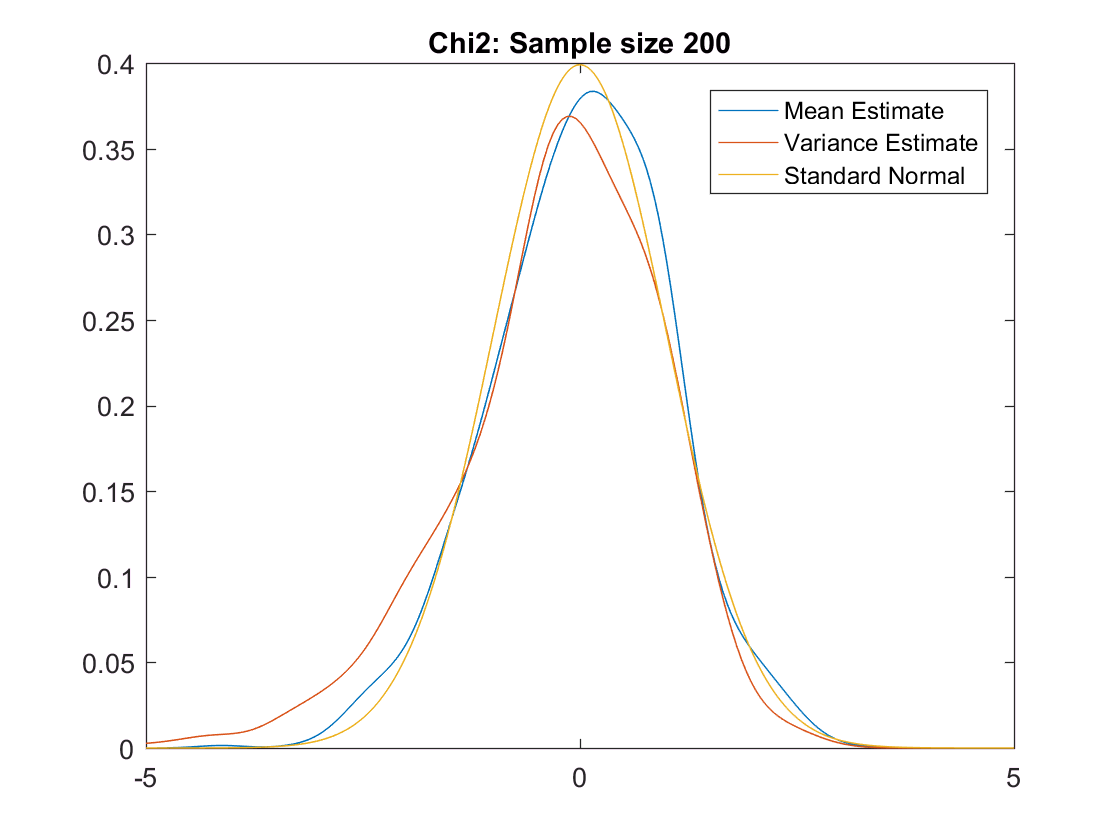

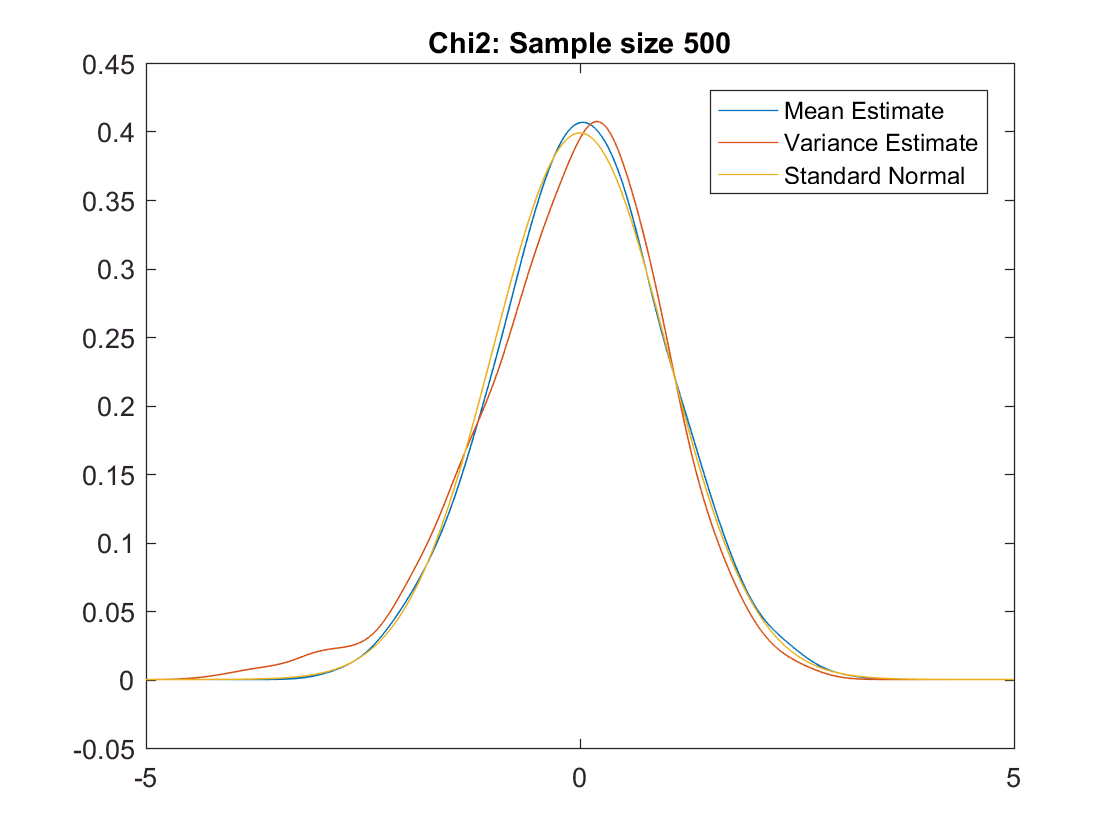

% M sets number of Monte Carlos
M = 1000;
% ns is sample sizes to use
ns = [5 10 50 100 200 500];
% Matrix to store biases
biases = zeros(length(ns),2);
for j=1:length(ns)
    % Set n for this run
    n = ns(j);
    % Matrices to hold outputs
    asymp_cov = zeros(2,2,M);
    parameters = zeros(M,2);
    % Loop across M
    for i=1:M
        x = chi2rnd(5,n,1);
        mu = mean(x);
        sigma2 = mean((x-mu).^2);
        parameters(i,:) = [mu sigma2];
        errors = [x - mu (x-mu).^2-sigma2];
        n = length(x);
        asymp_cov(:,:,i) = errors'*errors / n;
    end
    % Display some results
    disp('Sample size')
    disp(n)
    true_value = repmat([5 10],M,1);
    bias = mean(parameters - true_value);
    biases(j,:) = bias;
    disp('Bias')
    disp(bias)
    scaled_parameters = sqrt(n)*(parameters - true_value);
    disp('Covariance of estimates')
    cov_from_estimates = sqrt(diag(cov(scaled_parameters)));
    disp(cov_from_estimates)
    disp('Std Dev. from CLT')
    asymp_std_dev = sqrt(diag(mean(asymp_cov,3)));
    disp(asymp_std_dev)
    disp('Ratio - Estimates divided by Asymp.')
    disp(cov_from_estimates./asymp_std_dev)
    
    % Checking the Coverage
    std_err = zeros(1000,2);
    z = zeros(1000,2);
    for i=1:1000
        std_err = sqrt(diag(asymp_cov(:,:,i)/n));
        z(i,:) = (parameters(i,:) - [5 10])./std_err';
    end
    disp('10% CI coverage')
    disp(mean(abs(z) > norminv(.95)))
    disp('5% CI coverage')
    disp(mean(abs(z) > norminv(.975)))
    disp('1% CI coverage')
    disp(mean(abs(z) > norminv(.995)))
    
    % Density plot against a Standard normal
    figure(j)
    [~,f1,y1]=pltdens(z(:,1));
    [~,f2,y2]=pltdens(z(:,2));
    y3 = -5:.01:5;
    f3 = normpdf(y3,0,1);
    h = plot(y1,f1,y2,f2,y3,f3);
    legend('Mean Estimate','Variance Estimate','Standard Normal')
    ax = axis;
    ax(1) = -5;
    ax(2) = 5;
    axis(ax)
    title(['Chi2: Sample size ' num2str(n)])
end

## Bias plot

This plot shows the bias of the estimators against sample size. The mean is unbiased (as expected) while the variance has a negative bias (also expected).

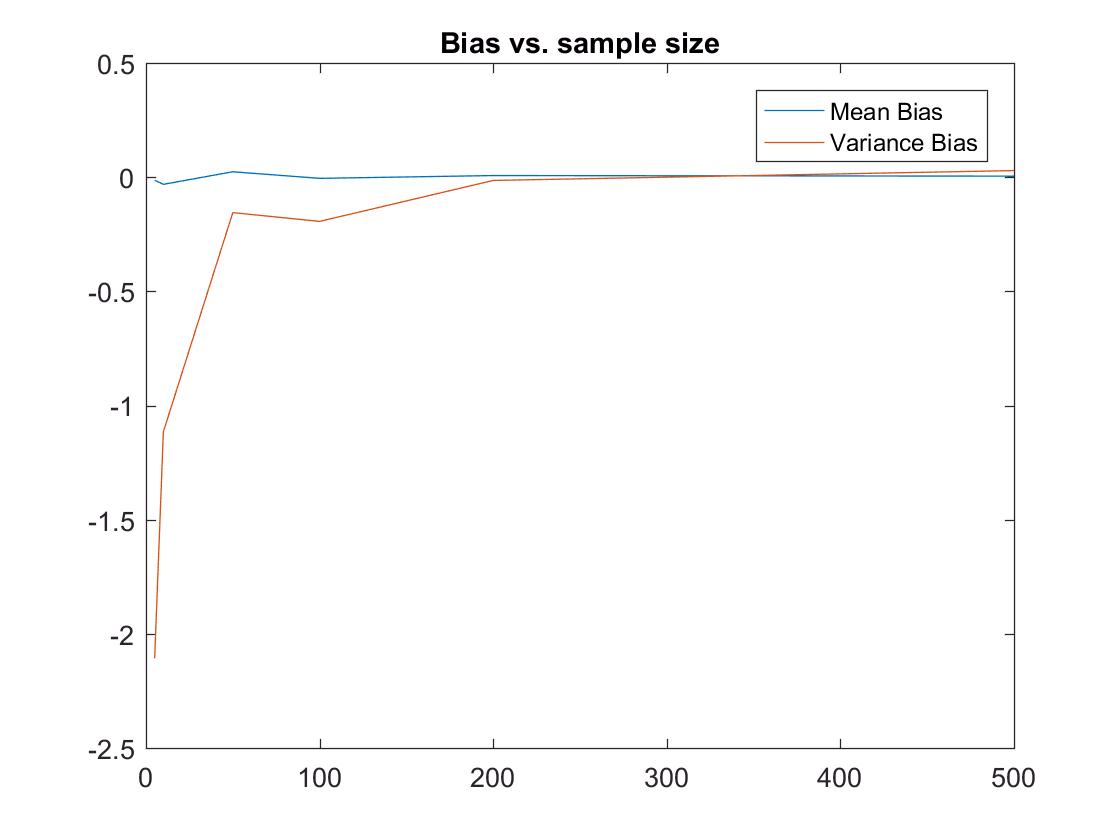

% Open new figure
figure(99)
% Plot biases
plot(ns,biases)
% Add a title
title('Bias vs. sample size')
% And a legend
legend('Mean Bias','Variance Bias')

## Probit Example

In the previous example, the bias is analytically tractable since the estimators are simple. In this example, the estimators are not analytically tractable and so a Monte Carlo is the only method to determine the extent and direction of bias.

## Bernoullis and Probit

This uses the previous set of tasks as the setup and so two loops are used to loop across sample sizes and the Monte Carlo iterations

% Setup options for no output
options = optimoptions('fminunc');
options.Display = 'off';
options.Algorithm = 'quasi-newton';

% Sample sizes
ns = [10 50 100 200 500 1000];
% Number of Monte Carlos
M = 1000;
for j=1:length(ns)
    % Number of simulations
    n = ns(j);
    % Matrices to hold information
    asymp_cov = zeros(2,2,M);
    probit_parameters = zeros(M,2);
    disp('Sample size')
    disp(n)
    disp('Iteration')
    for i=1:M
        % Display progress every 100 iterations
        if mod(i,100)==0
            disp(i)
        end
        % Exogenous variables
        x = randn(n,1);
        % Transform to probabilities
        p = normcdf(x);
        % 1 is a uniform is larger than p
        y = p>rand(n,1);
        
        % Optimize the log-likelihoods
        probit_parameters(i,:) = fminunc(@probit_loglike,[0 1],options,y,x);
        
        % Compute scores
        a0 = probit_parameters(i,1);
        a1 = probit_parameters(i,2);
        pdf = normpdf(a0+a1*x);
        cdf = normcdf(a0+a1*x);
        scores_a0 = y .* pdf ./ cdf - (1-y) .* pdf ./ (1-cdf);
        scores_a1 = y .* x .* pdf ./ cdf - (1-y) .* x  .* pdf ./ (1-cdf);
        
        scores = [scores_a0 scores_a1];
        % Covariance is inv of covariance of scores
        asymp_cov(:,:,i) = inv(scores'*scores / n);
    end
    % Report statistics
    disp('Sample Size')
    disp(n)
    disp('Bias')
    bias = mean(probit_parameters) - [0 1];
    disp(bias)
    disp('Ratio of finite sample variance to avg. asymp variance')
    disp(diag(n*cov(probit_parameters))./diag(mean(asymp_cov,3)))
    
    % Checking the Coverage
    % Code is the same as above
    std_err = zeros(M,2);
    z = zeros(M,2);
    for i=1:M
        std_err = sqrt(diag(asymp_cov(:,:,i)/n));
        z(i,:) = (probit_parameters(i,:) - [0 1])./std_err';
    end
    disp('10% CI coverage')
    disp(mean(abs(z) > norminv(.95)))
    disp('5% CI coverage')
    disp(mean(abs(z) > norminv(.975)))
    disp('1% CI coverage')
    disp(mean(abs(z) > norminv(.995)))
    
    % Density plot against a Standard normal
    figure(100+j)
    % pltdens to compute f and y
    [~,f1,y1]=pltdens(z(:,1));
    [~,f2,y2]=pltdens(z(:,2));
    y3 = -5:.01:5;
    f3 = normpdf(y3,0,1);
    % Plot and legend
    h = plot(y1,f1,y2,f2,y3,f3);
    legend('a0 Estimate','a1 Estimate','Standard Normal')
    ax = axis;
    ax(1) = -5;
    ax(2) = 5;
    axis(ax)
    title(['Probit: Sample size ' num2str(n)])
end